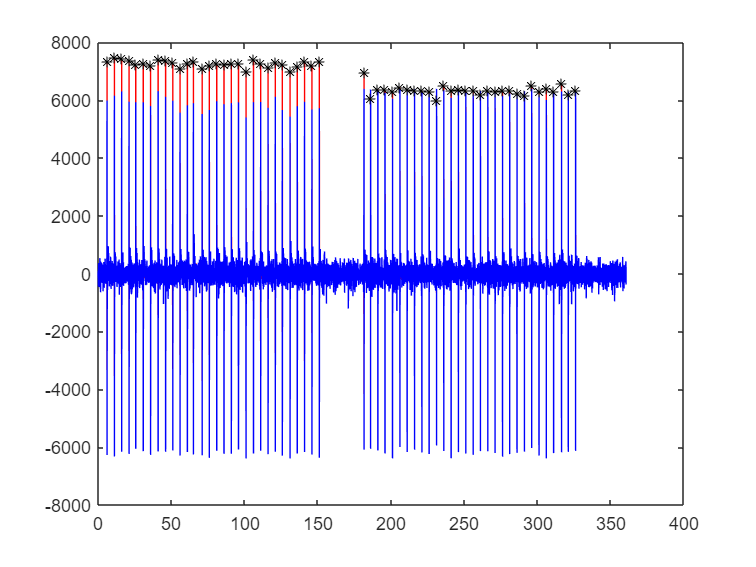

clc
clear all

datadir='C:\Users\giuse\Desktop\1.5 ANNO\NSA\project\NSA_data\ET1\R21-16\PreLesion_Mapping';
x=load(fullfile(datadir,"Raw_P2_Ch_010.mat"));
x=double(x.data);

datadir='C:\Users\giuse\Desktop\1.5 ANNO\NSA\project\NSA_data\ET1\R21-16\PostLesion_Mapping';
y=load(fullfile(datadir,"Raw_P2_Ch_010.mat"));
y=double(y.data);

if length(y) < length(x)
    x=x(1:length(y));
else
    y=y(1:length(x));
end
low_range= 300;
high_range=3000;
filter_order=2;
fc=25000;
range = [low_range high_range]; % frequency range
bandwidth = fc/2; % half of sampling rate
[B,A]=butter(filter_order,range./bandwidth);
xf = filtfilt(B,A,x);
yf = filtfilt(B,A,y);
[aax,ax]=findpeaks(xf, 'MinPeakHeight',500,'MinPeakDistance',25000);
[aay,ay]=findpeaks(yf, 'MinPeakHeight',500,'MinPeakDistance',25000);
RP=25;
% thx=4*1.4826*mad(xf(3800000:4400000),1)
% thy=4*1.4826*mad(yf(3800000:4400000),1)
wdw_length=50;
thx=7*std(xf(ax(end)+10000:end));
thy=7*std(yf(ay(end)+10000:end));
%thy = mean(yf(ay(end)+10000:end)) + 3*std(yf(ay(end)+10000:end));
% thy = 3*4*1.4826*mad(yf(ay(end)+10000:end));
[ampx,stx] = differential_th(xf, wdw_length, thx);
[ampy,sty] = differential_th(yf, wdw_length, thy);
% [ampx,stx]=findpeaks(abs(xf), 'MinPeakHeight',thx, 'MinPeakDistance', RP);
% [ampy,sty]=findpeaks(abs(yf), 'MinPeakHeight',thy, 'MinPeakDistance', RP);
t = (1:length(xf))/fc;
figure
plot(t,xf,'r')
hold on
plot(t,x,'b')
hold on
plot(ax/fc,aax,'k*')

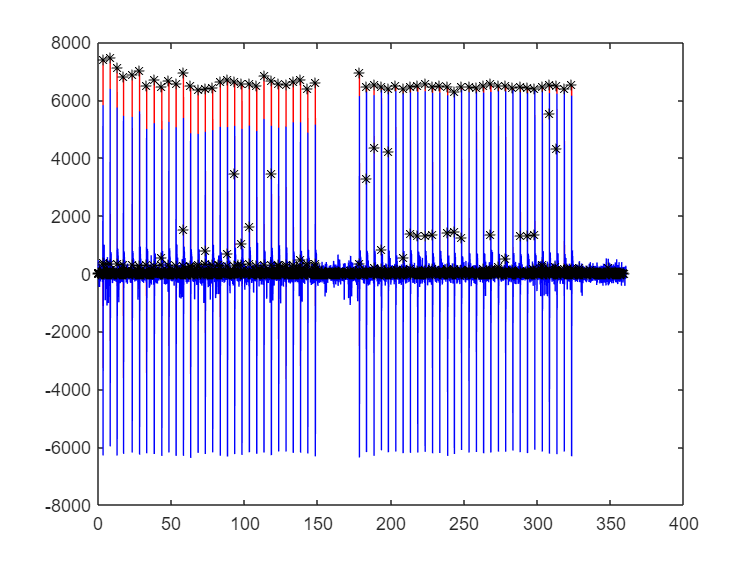

figure
plot(t,yf,'r')
hold on
plot(t,y,'b')
hold on
plot(sty/fc,ampy,'k*')

wdwsize = 0.4; % sec - wdw after stimulus 
wdw = wdwsize*fc;
binsize = 0.01; % sec 
bin= binsize*fc;

nbins = wdwsize/binsize;
num_bin = wdw/bin;

% artifact_pos=ax;
% peak_pos=stx;
% num_bin = wdw/bin;
%     psth_output=zeros(length(artifact_pos),num_bin);
% mfr=[];
%     for itrigger = 1:length(artifact_pos)
%         
%         stimulus_wdw = peak_pos(peak_pos > artifact_pos(itrigger) & peak_pos <= artifact_pos(itrigger)+wdw);
%         mfr=[mfr,stimulus_wdw'];
% 
%         for ibin = 1:num_bin
%             
%             peak_in_bin = stimulus_wdw(stimulus_wdw > artifact_pos(itrigger)+bin*(ibin-1) & stimulus_wdw <= artifact_pos(itrigger)+bin*ibin);
%             
%             psth_output(itrigger,ibin) = length(peak_in_bin);
%         end
%     end

%     mfr=mfr-mfr(1)+1;
%   figure
%   hresp=gca;
%     times=mfr;
%    triallen=ax(2)-ax(1);
%    numtrials=length(ax);
%    trialgap=1.5;
%     trials=ceil(times/triallen);
%   reltimes=mod(times,triallen);
%   reltimes(~reltimes)=triallen;
%   numspikes=length(times);
%   xx=ones(3*numspikes,1)*nan;
%   yy=ones(3*numspikes,1)*nan;
%   yy(1:3:3*numspikes)=(trials-1)*trialgap;
%   yy(2:3:3*numspikes)=yy(1:3:3*numspikes)+1;
%   fs=25000;
%   %scale the time axis to ms
%   xx(1:3:3*numspikes)=reltimes*1000/fs;
%   xx(2:3:3*numspikes)=reltimes*1000/fs;
%   xlim=[1,triallen*1000/fs];
%   axes(hresp)
%   plot(xx, yy, 'k', 'linewidth',1)
%   axis ([xlim,0,(numtrials)*1.5])

% jj=xx(1:100);
% ii=yy(1:100);
% figure
% plot(jj,ii,'linewidth',1)

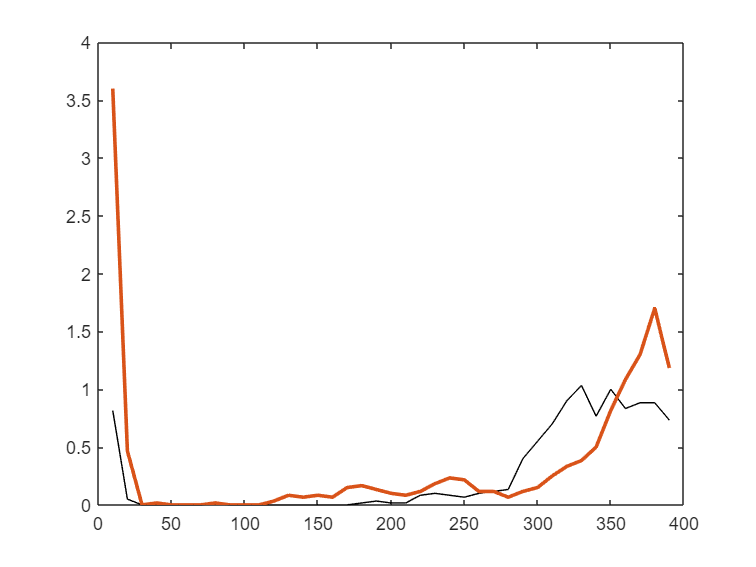

% ggg=[1 2 3 nan 4 5 9];
%   ooo=[0 1 nan 4 7 8 9];
%   figure
%   plot(ggg,ooo)



[psthx, mfrx]=psth(stx, wdw, bin, ax);
[psthy, mfry]=psth(sty, wdw, bin, ay);


% corrx=[3*ones(length(ax),1),zeros(length(ax),num_bin-1)];
% corry=[3*ones(length(ay),1),zeros(length(ay),num_bin-1)];
% psthx=psthx-corrx;
% psthy=psthy-corry;
countx = mean(psthx,1);
county = mean(psthy,1);
time = 10:binsize*1000:wdwsize*1000-1;
figure
plot(time, countx(1,2:end),'k')
%hold on
%plot(time, countx+std(psthx,1))
%hold on
%plot(time, countx-std(psthx,1))
hold on
plot(time, county(1,2:end),'LineWidth',2)

% hold on
% plot(time, county+std(psthy,1),'LineWidth',2)
% hold on 
% plot(time, county-std(psthy,1))

% maria = trapz(time,countx);
% sina = trapz(time,county);
% diff=maria-sina;